Guardar Resultados Linea Base, Filas corresponden  a diferentes densidades y columnas a diferente tasa de beaconing.

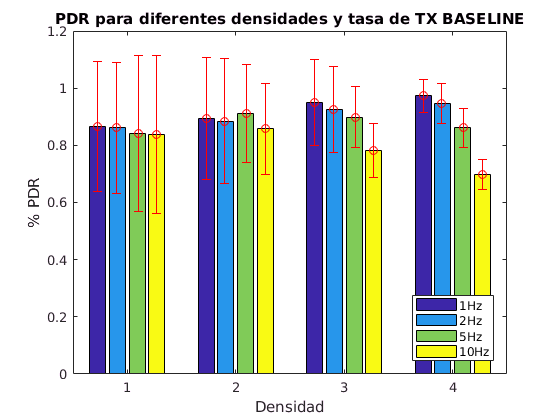


PDR_MEAN(1,:) = [[0.8654912022155908], [0.8616271036015288], [0.8411713976796562], [0.8378115271562594]];
PDR_MEAN(2,:) =[[0.8936375858505483], [0.883719094170653], [0.9110577115819203], [0.857238734390732]];
PDR_MEAN(3,:) =[[0.9496919443616982], [0.926028318356899], [0.89911858822504], [0.7824706905747228]];
PDR_MEAN(4,:) = [[0.9732149364045741], [0.9467093609468915], [0.8611097581294315], [0.696442833301333]];

PDR_STD(1,:)= [[0.2286578406633056], [0.2297565987939423], [0.2714610613145504], [0.2754871029731717]];
PDR_STD(2,:)= [[0.21476080143615822], [0.21899442655191176], [0.17238361145884498], [0.15755053151629375]];
PDR_STD(3,:)= [[0.15106787113149972], [0.15118787656828714], [0.1073025769016769], [0.09549497900179281]];
PDR_STD(4,:)= [[0.05683149702961439], [0.06940975421786656], [0.06755428427926098], [0.052265795018918225]];

CBR_MEAN(1,:) = [[0.0008698821405228759], [0.0017406641861850325], [0.006107561103263765], [0.012620158887251941]];
CBR_MEAN(2,:) = [[0.0068713497020953425], [0.013399237334635515], [0.03736432380294872], [0.07356855487189694]];
CBR_MEAN(3,:) = [[0.01566743747630353], [0.030767541354059635], [0.07765933419250752], [0.1432408055082282]];
CBR_MEAN(4,:) = [[0.0257366870204798], [0.05108984286396726], [0.1171330106818622], [0.2010621634273534]];

CBR_STD(1,:) = [[0.0003165845415401063], [0.0006281062323748147], [0.0020057174279604845], [0.00390355418994932]];
CBR_STD(2,:) = [[0.00177403136095693], [0.0030316557997442533], [0.008251623321974802], [0.01627534909127408]];
CBR_STD(3,:) = [[0.0026320584784223114], [0.005115705472916481], [0.0129083663474471], [0.023887223748478317]];
CBR_STD(4,:) = [[0.003774719986107302], [0.00603870473325179], [0.014823486247616454], [0.025917029777481962]];


figure (1)
bar(PDR_MEAN,'DisplayName','PDR_MEAN')
hold on

title('PDR para diferentes densidades y tasa de TX BASELINE');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,PDR_MEAN,PDR_STD,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
hold off

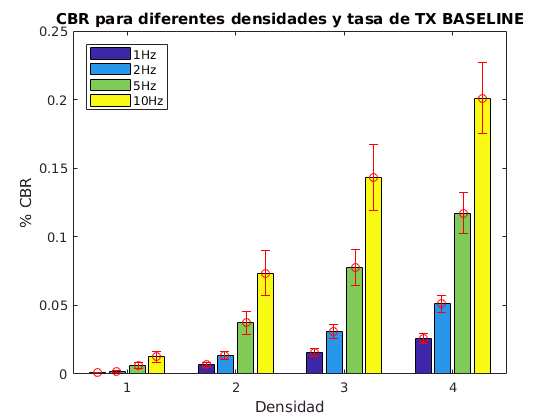

figure (2)

bar(CBR_MEAN,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX BASELINE');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN,CBR_STD,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

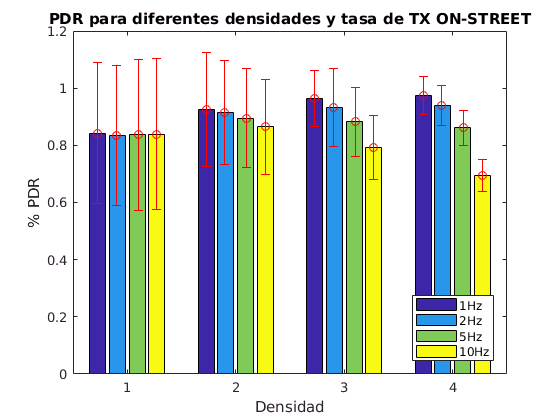


PDR_MEAN_OS(1,:) = [[0.8426205974452508], [0.8346363751287217], [0.8365348498490423], [0.8386509781502812]];
PDR_MEAN_OS(2,:) = [[0.9250858846267641], [0.915174909562228], [0.8949645836848171], [0.8652118413448525]];
PDR_MEAN_OS(3,:) = [[0.9643965469237262], [0.9317178213338514], [0.8817768202837557], [0.7915821911472094]];
PDR_MEAN_OS(4,:) = [[0.973585435517895], [0.9401257517417846], [0.8609911864270003], [0.6935028672800541]];
%Promedio CBR:
CBR_MEAN_OS(1,:) = [[0.0008108629833659593], [0.0019417118473023744], [0.004237779225826416], [0.008037132381497206]];
CBR_MEAN_OS(2,:) = [[0.007186643313838577], [0.01465439606660042], [0.035403277492475814], [0.06792944586739608]];
CBR_MEAN_OS(3,:) = [[0.01609128200302367], [0.031946944759751524], [0.07578504721957596], [0.1423176724733219]];
CBR_MEAN_OS(4,:) = [[0.025770490030410168], [0.050744303608064784], [0.116440125861422], [0.20071925906130608]];
%STD PDR:
PDR_STD_OS(1,:) = [[0.24719133637632978], [0.24400765113997624], [0.2640469968457279], [0.2639293244910688]];
PDR_STD_OS(2,:) = [[0.19964144404106765], [0.18091281013102958], [0.17281549503688104], [0.1665246490258682]];
PDR_STD_OS(3,:) =[[0.09779442171763411], [0.13578566243048557], [0.12168447142322245], [0.11181391297234877]];
PDR_STD_OS(4,:) =[[0.06743950172515666], [0.0696032614772331], [0.06220027121814096], [0.05561574299952833]];
%STD CBR:
CBR_STD_OS(1,:) =[[0.0002853472057689172], [0.0007943267856496094], [0.0015280508228279444], [0.0026319374150984964]];
CBR_STD_OS(2,:) =[[0.001541265579230168], [0.0036452616217798484], [0.00700055153836065], [0.013769458476519201]];
CBR_STD_OS(3,:) =[[0.0026361643536416254], [0.005754479378625986], [0.012210302834405171], [0.023237919615618274]];
CBR_STD_OS(4,:) =[[0.0031685916050777454], [0.00676174006842133], [0.0154208747689443], [0.024406884309339322]];



figure (3)
bar(PDR_MEAN_OS,'DisplayName','PDR_MEAN_OS')
hold on

title('PDR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,PDR_MEAN_OS,PDR_STD_OS,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
hold off

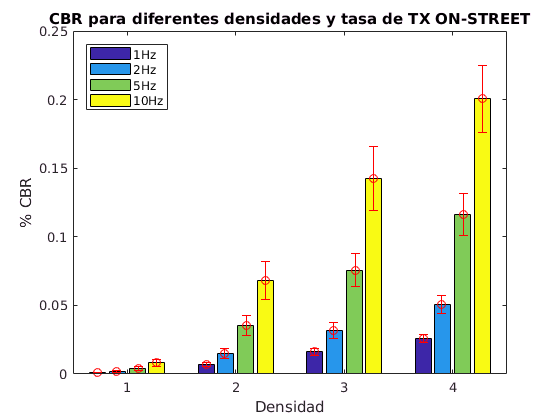

figure (4)

bar(CBR_MEAN_OS,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN_OS,CBR_STD_OS,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

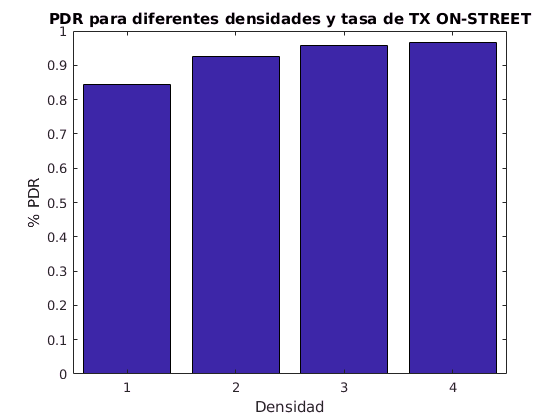

PDR_MEAN_MultiTX(1,:) = [[0.8427834203179689], [], [], []];
PDR_MEAN_MultiTX(2,:) = [[0.9270032971606375], [], [], []];
PDR_MEAN_MultiTX(3,:) = [[0.9568247118024398], [], [], []];
PDR_MEAN_MultiTX(4,:) = [[0.967607024509874], [], [], []];
%Promedio CBR:
CBR_MEAN_MultiTX(1,:) = [[0.0008912284783675102], [], [], []];
CBR_MEAN_MultiTX(2,:) = [[0.006840211870624369], [], [], []];
CBR_MEAN_MultiTX(3,:) = [[0.01642780210428171], [], [], []];
CBR_MEAN_MultiTX(4,:) = [[0.02541306148892013], [], [], []];
%STD PDR:
PDR_STD_MultiTX(1,:) = [[0.25715677594551695], [], [], []];
PDR_STD_MultiTX(2,:) = [[0.18388250312165352], [], [], []];
PDR_STD_MultiTX(3,:) = [[0.11718624478894195], [], [], []];
PDR_STD_MultiTX(4,:) = [[0.07214143227193322], [], [], []];
%STD CBR:
CBR_STD_MultiTX(1,:) = [[0.00031541935910736727], [], [], []];
CBR_STD_MultiTX(2,:) = [[0.0016307204089330942], [], [], []];
CBR_STD_MultiTX(3,:) = [[0.0028392694457956397], [], [], []];
CBR_STD_MultiTX(4,:) = [[0.0032110258097078972], [], [], []];





figure (5)
bar(PDR_MEAN_MultiTX,'DisplayName','PDR_MEAN_OS')
hold on

title('PDR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% PDR');


x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;
size(PDR_MEAN_MultiTX(:,1))

ans =      4     1


size(PDR_STD_MultiTX(:,1))

ans =      4     1


size(x2)

ans =      4     4


errorbar(x2,PDR_MEAN_MultiTX(:,1)',PDR_STD_MultiTX(:,1)','ro');

Error using errorbar>checkSingleInput (line 264)
XData must be the same size as YData.

Error in errorbar (line 94)
x = checkSingleInput(x, sz, 'XData');

legend('MultiTX','Location','SouthEast');
hold off


figure (6)

bar(CBR_MEAN_MultiTX,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN_MultiTX,CBR_STD_MultiTx,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off


